# Generate Experimental Data

## Open Model

modelName = 'gasTurbine';
open_system(modelName)
train = true; % enable or disable network trainning

## Generate Simulation Scenarios

Set the simulation stop time in (s)

simStopTime = 500;

Create different simulation scenarios by specifying the shaft speed vector

shaftSpeedStates = {{[4e3:1e3:1e4],simStopTime},
                    {[4.2e3:1e3:1.2e4],simStopTime},
                    % {[[4e3:1e3:8e3] [8e3:-1e3:4e3]] ,simStopTime},
                    % {[[5e3:1e3:9e3] [9e3:-1e3:5e3]] ,simStopTime},
                    % {[[6e3:1e3:10e3] [10e3:-1e3:6e3]] ,simStopTime},
                    {[5e3:0.5e3:1.1e4], simStopTime},
                    {[6e3:0.5e3:1.1e4], simStopTime},
                    % {[[4e3:1e3:12e3] [12e3:-1e3:4e3]] ,simStopTime},
                    {[7e3:0.5e3:1.1e4], simStopTime},
                    {[8e3:0.5e3:1.1e4], simStopTime},
                    {[9e3:0.5e3:1.1e4], simStopTime},
                    {[4.5e3:1e3:1.1e4], simStopTime},
                    };


Generate the scenatios and save them in MAT files

for ix=1:numel(shaftSpeedStates)
    generateShaftSpeedInputs(scenarioDir, shaftSpeedStates{ix}{1},...
    shaftSpeedStates{ix}{2}, 'stairOnly', ix)
end

## Generate Simulink Simulation Inputs

From the generated scenarios you can create "Simulink.SimulationInputs"

clearvars simIn
fileList = listSimInpFiles(scenarioDir);
numCases = length(fileList);
scenario = {};
for ix=1:numCases
    fileName = split(fileList{ix},'.');
    scenario{ix} = load(fileList{ix});
    aux = split(fileName{1},'_');
    simStopTime = aux{end};
    simIn(ix) = Simulink.SimulationInput(modelName);
    simIn(ix) = simIn(ix).setModelParameter('StopTime', simStopTime);    

Initialize compressor's RPM with respect to the Simulation scenarios

    rpm0 = aux{2};
    simIn(ix) = setVariable(simIn(ix), 'rpm0', str2num(rpm0), ...
        'Workspace', modelName);  
    simIn(ix) = setVariable(simIn(ix), 'rpm_setpoint', scenario{ix}.shaftSpeedRef{1}.Values.Data', ...
        'Workspace', modelName);    
    simIn(ix) = setVariable(simIn(ix),'time_setpoint', scenario{ix}.shaftSpeedRef{1}.Values.Time', ...
        'Workspace', modelName);
end

## Simulate and Save

out = parsim(simIn);

[11-Sep-2023 20:16:19] Checking for availability of parallel pool...
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 12 workers.
[11-Sep-2023 20:16:41] Starting Simulink on parallel workers...
[11-Sep-2023 20:16:48] Loading project on parallel workers...
[11-Sep-2023 20:16:48] Configuring simulation cache folder on parallel workers...
[11-Sep-2023 20:16:54] Loading model on parallel workers...
[11-Sep-2023 20:17:02] Running simulations...
[11-Sep-2023 20:17:20] Completed 1 of 8 simulation runs
[11-Sep-2023 20:17:20] Completed 2 of 8 simulation runs
[11-Sep-2023 20:17:21] Completed 3 of 8 simulation runs
[11-Sep-2023 20:17:21] Completed 4 of 8 simulation runs
[11-Sep-2023 20:17:21] Completed 5 of 8 simulation runs
[11-Sep-2023 20:17:21] Completed 6 of 8 simulation runs
[11-Sep-2023 20:17:21] Completed 7 of 8 simulation runs
[11-Sep-2023 20:17:21] Completed 8 of 8 simulation runs
[11-Sep-2023 20:17:21] Cleaning up parallel workers...


save(fullfile(simOutDir,'simOuts'),'out') 

# Configure Data for Training

To achieve better performance the data are resampled, normalized and split in trainning and validation data.

## Resample Data

Resample the date in seconds

resampleTimeStep = 1; % (s)
scaleFactor = 1; % rescale the date
trainData = prepareTrainingData(out, resampleTimeStep, scaleFactor,1); 

## Inspect resampled data

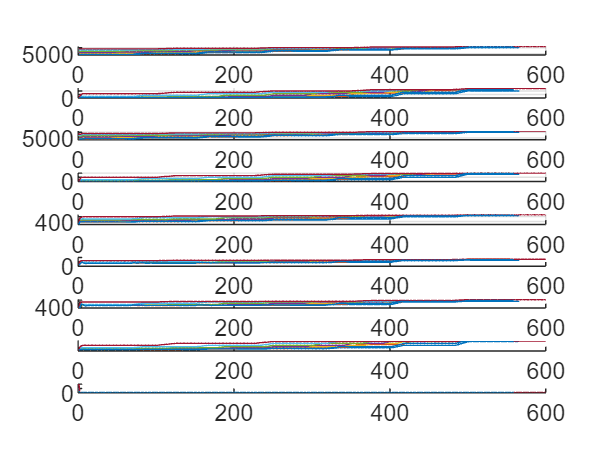

Index exceeds the number of array elements. Index must not exceed 5.

Error in visualizeTrainData (line 23)
    ylabel(ax{ix},signalNames{ix})

signalNames = {'Nref','Phi','N', 'MechPower', 'T3'};
visualizeTrainData(trainData(:),signalNames, 'Resampled Data')

## Partition trainning data

trainPercentage = 1; % the percentage of the data that they will be used for training
                       % the rest will be used for test

[dataTrain, dataTest] = trainPartitioning(trainData, trainPercentage);


## Normalize data

Merge training and validation data

concatDataTrain = [];
for ix=1:numel(dataTrain)
    concatDataTrain = cat(2,concatDataTrain,dataTrain{ix}(:,:));
end

concatDataTest = [];
for ix=1:numel(dataTest)
    concatDataTest = cat(2,concatDataTest,dataTest{ix}(:,:));
end

### Visualize Traning and Validation Data

figure
T = array2table([concatDataTrain'], VariableNames=["Reference RPM","Phi","RPM","Mech Power","T3"]);

Error using array2table
The VariableNames property must contain one name for each variable in the table.

stackedplot(T)

if not(isempty(concatDataTest))
figure
T2 = array2table([concatDataTest'], VariableNames=["Reference RPM","Phi","RPM","Mech Power","T3"]);
stackedplot(T2)
end

### Calculate Mean and Standard Deviation

clear XTrainNormalized YTrainNormalized normTrain normVal
XTrain = concatDataTrain;
XVal = concatDataTest;

if not(isempty(concatDataTest))
YTrain = XTrain(2:end,:);
YVal = XVal(2:end,:);
end

% Normalize training and validation data
for ix=1:size(XTrain,1)
    meanTrain(ix) = mean(XTrain(ix,:));
    stdTrain(ix) = std(XTrain(ix,:));
if not(isempty(concatDataTest))    
    meanVal(ix) = mean(XVal(ix,:));
    stdVal(ix) = std(XVal(ix,:));
end

end

## Normalize data

Normalize train scenarios

normalize = @(x,mu,sigma) (x - mu) ./ sigma;
dataTrainNorm = [];
for iy=1:size(dataTrain,2)
    normTrainSep = [];
    % Normalize train data
    for ix=1:size(dataTrain{iy},1)
        normTrainSep(ix,:) = normalize(dataTrain{iy}(ix,:),meanTrain(ix), stdTrain(ix));
    end
    dataTrainNorm{iy} = normTrainSep;
end

Normalize validation scenarios

dataValNorm=[];
for iy=1:size(dataTest,2)
    normValSep = [];
    for ix=1:size(dataTest{iy},1)
        normValSep(ix,:) = normalize(dataTest{iy}(ix,:),meanVal(ix), stdVal(ix));
    end
    dataValNorm{iy} = normValSep;
end


Generate normalized trainning and validation datasets

% Preprocess
outStartIdx = 2;
XTrainSep = {};
TTrainSep = {};
[XTrainSep, TTrainSep] = preprocessTrainData(dataTrainNorm, outStartIdx);
[XTestSep, TTestSep] = preprocessTrainData(dataValNorm, outStartIdx);

## Inspect Train and Test Data

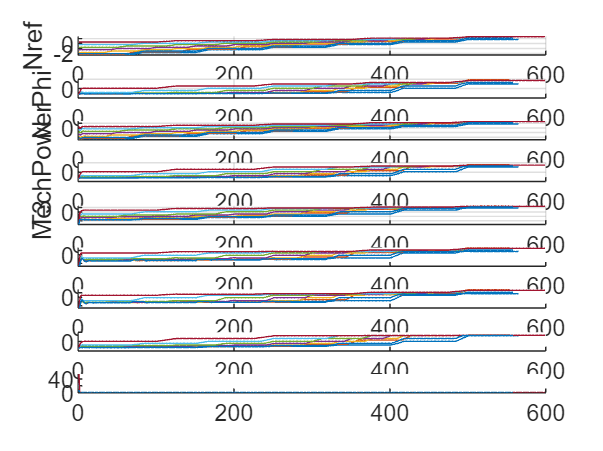

Index exceeds the number of array elements. Index must not exceed 5.

Error in visualizeTrainData (line 23)
    ylabel(ax{ix},signalNames{ix})

visualizeTrainData(XTrainSep(:),signalNames, 'Train Data')

visualizeTrainData(XTestSep(:),signalNames, 'Test Data')

# Define Network Architecture

## Inputs outputs

Define inputs/outputs dimensions

numFeatures = 9;
numResponses = 8;
outStartIdx = 2;


# Train Neural Network

Define the network architecture:

layers = [
    sequenceInputLayer(numFeatures,"Name","input")
    lstmLayer(numHiddenUnits,"Name","lstm","OutputMode","sequence")
    dropoutLayer(dropoutProbability,"Name","drop")
    fullyConnectedLayer(numHiddenUnits,"Name","fc_1")
    reluLayer("Name","relu")
    fullyConnectedLayer(numResponses,"Name","fc_2")
    regressionLayer("Name","regressionoutput")
    ];

Define the trainning options:

opts = trainingOptions("adam",...
    "ExecutionEnvironment","auto",...
    "InitialLearnRate",0.01,...
    "MaxEpochs",1000,...
    "Shuffle","every-epoch",... 
    "LearnRateSchedule","piecewise",...
    "LearnRateDropPeriod",200,...
    "LearnRateDropFactor",0.1,...
    "ValidationFrequency",10,...
    "Plots","training-progress");
    % "ValidationData",{XTestSep,TTestSep},...


Train the network:

Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |         2.60 |          3.4 |          0.0100 |
|      50 |          50 |       00:00:03 |         0.22 |      2.4e-02 |          0.0100 |
|     100 |         100 |       00:00:05 |         0.17 |      1.4e-02 |          0.0100 |
|     150 |         150 |       00:00:07 |         0.15 |      1.1e-02 |          0.0100 |
|     200 |         200 |       00:00:09 |         0.14 |      9.4e-03 |          0.0100 |
|     250 |         250 |       00:00:11 |         0.13 |      9.0e-03 |          0.0010 |
|     300 |         300 |       00:00:13 |         0.13 |      9.1

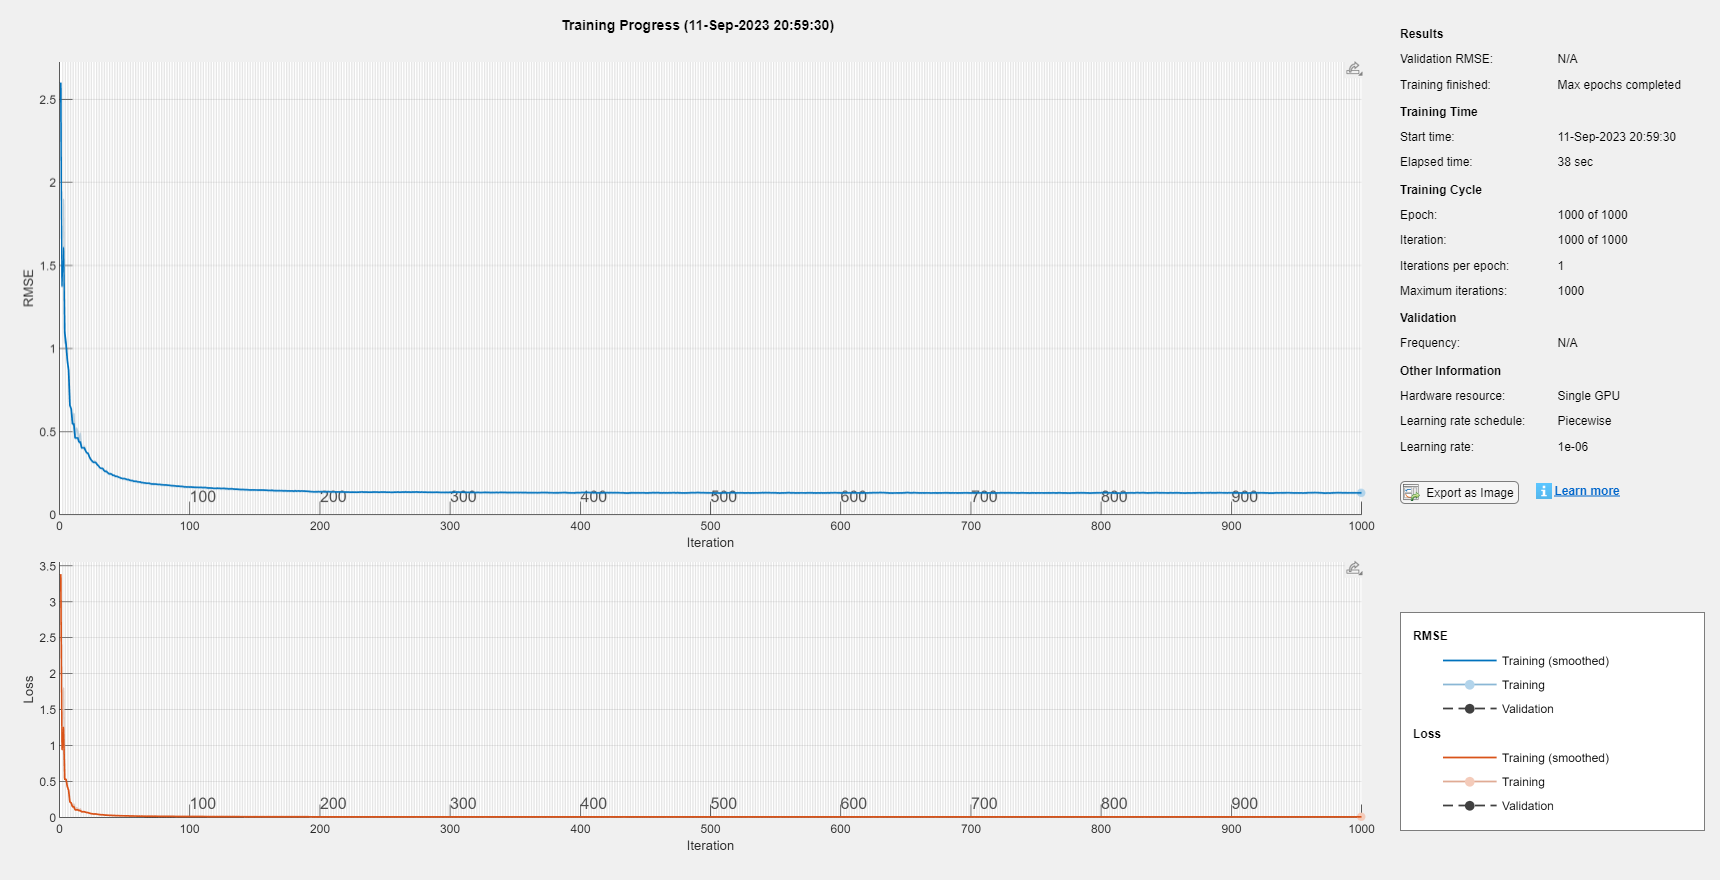

if train
    [net, traininfo] = trainNetwork(XTrainSep,TTrainSep,layers,opts);
    net = resetState(net);
end

Save the network

save(fullfile(proj.RootFolder, 'Demo','braytonLSTMNetThermo'), 'net')

## Check Neural Network response

%% Inspect NN response
% mean(dev{1})
% std(dev{1})
results = getLSTMResponses(XTrainSep, TTrainSep, net)

results = 1×12 cell array
    {4×563 double}    {4×598 double}    {4×557 double}    {4×564 double}    {4×552 double}    {4×540 double}    {4×540 double}    {4×539 double}    {4×523 double}    {4×538 double}    {4×521 double}    {4×548 double}


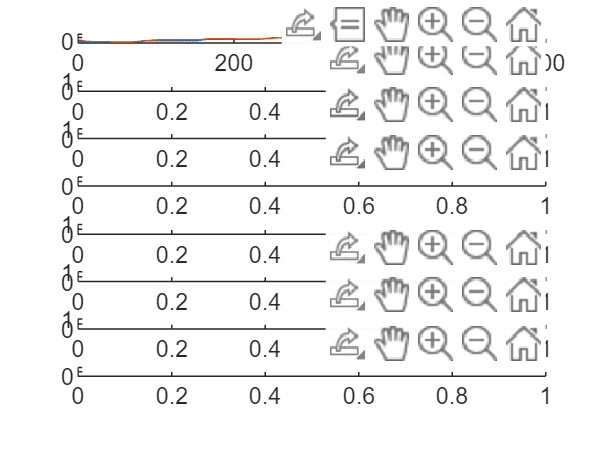

% dev = compareResponses(TTrainSep, results, signalNames(outStartIdx:end), 'NN Response');

## Open loop prediction - Update States

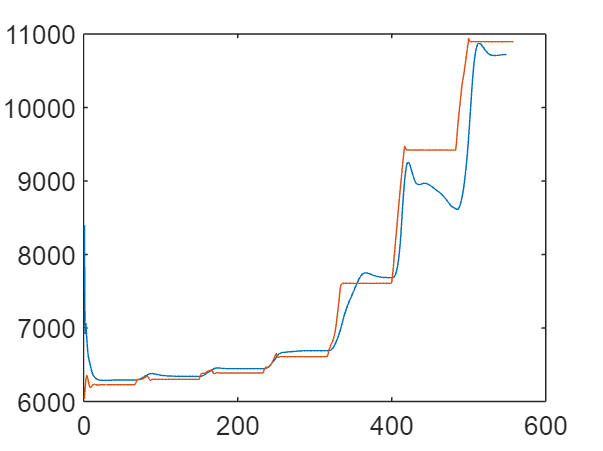

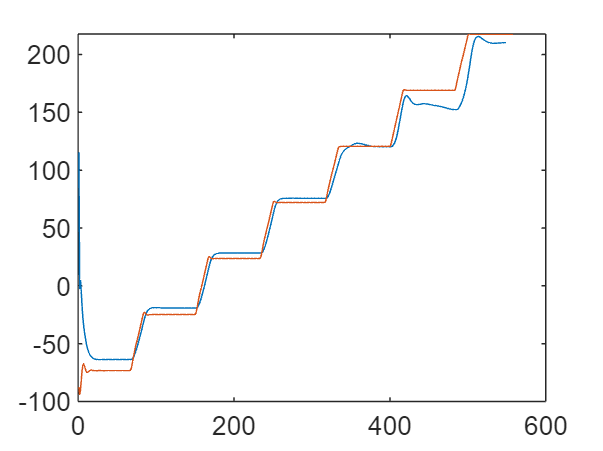

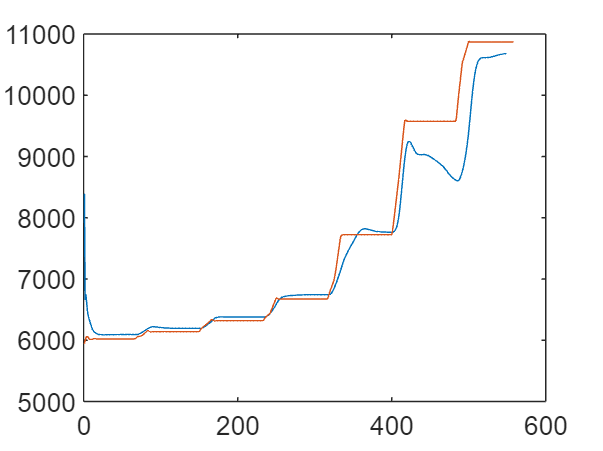

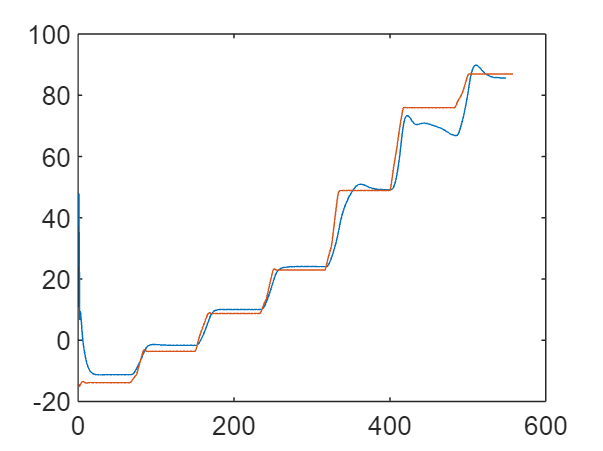

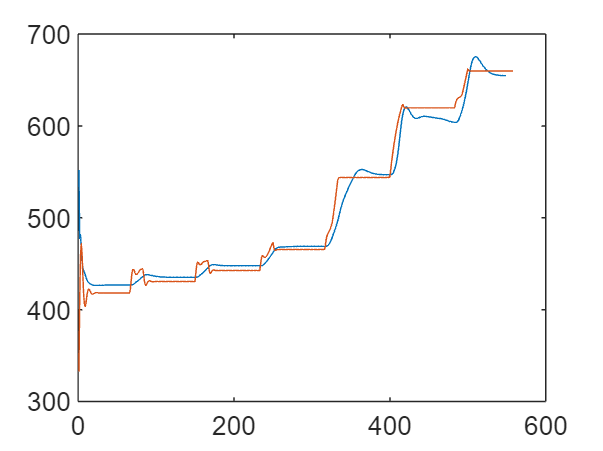

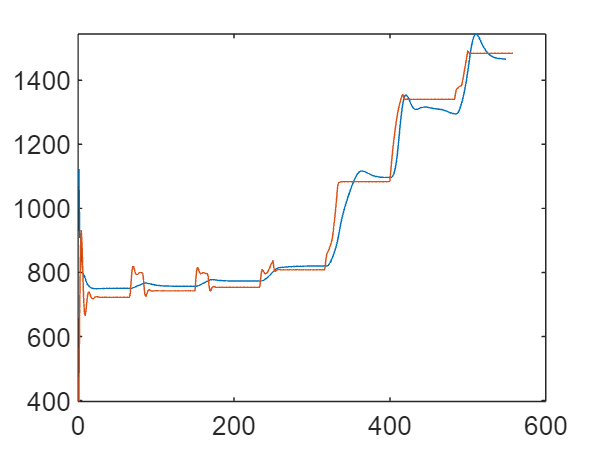

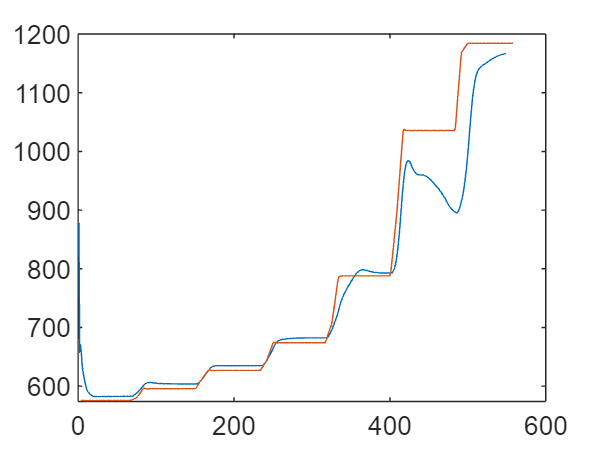

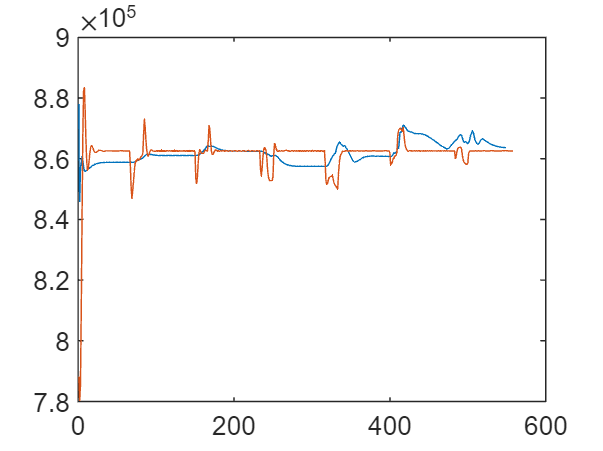

idx = 8;
X = XTrainSep{idx};
TY = TTrainSep{idx};

net = resetState(net);
offset = 9;
[net,~] = predictAndUpdateState(net,X(:,1:offset));

numTimeSteps = size(X,2);
numPredictionTimeSteps = numTimeSteps - offset;
Y = zeros(numResponses,numPredictionTimeSteps);


for t = 2:numPredictionTimeSteps
    Xt = [X(1,t-1);Y(:,t-1)];
    [net,Y(:,t)] = predictAndUpdateState(net,Xt);
end

for inspSig=1:numResponses
figure
plot(Y(inspSig,:)'*stdTrain(inspSig)+meanTrain(inspSig))
hold on
plot(TY(inspSig,:)'*stdTrain(inspSig)+meanTrain(inspSig))
hold off
end

## Simulate ROM model

modelROM = 'brayton_cycle_LSTM_ROM';
clearvars simInROM
scenarioIdx = 1;
testScenario = scenario{scenarioIdx};  
simInROM = Simulink.SimulationInput(modelROM);

% Initialize compressor's RPM with respect to the Simulation scenarios
rpm0 = testScenario.shaftSpeedRef{1}.Values.Data(1);
simInROM = setVariable(simInROM, 'rpm0', rpm0, ...
    'Workspace', modelName);  
simInROM = setVariable(simInROM, 'rpm_setpoint', testScenario.shaftSpeedRef{1}.Values.Data', ...
    'Workspace', modelName);    
simInROM = setVariable(simInROM,'time_setpoint', testScenario.shaftSpeedRef{1}.Values.Time', ...
    'Workspace', modelName);


## Simulate ROM

outROM = sim(simInROM);

## Compare ROM with initial model


import matlab.unittest.TestCase
import Simulink.sdi.constraints.MatchesSignal
import Simulink.sdi.constraints.MatchesSignalOptions
% Create a test case:
testCase = TestCase.forInteractiveUse;    

% Set accepted tolerance
relTol = 1e-1;

% Map log signals
dic = {};
dic{1} = 2;
dic{2} = 1;
dic{3} = 4;

% Compare different signals between ROM LSTM model and original model.
for ix=1:outROM.logsout.numElements-1
        testCase.verifyThat(outROM.logsout{ix},MatchesSignal(out(scenarioIdx).logsout{dic{ix}},'RelTol',1e-4))
end